# One Patient

Analyze data about one patient:

- Extract EEG data

- Apply Laplacian filter and compute PSD

- Choose discriminant features using Fisher score

- Train and save a classifier

- Evaluate performance with and without evidence accumulation

patients = find_patients('eeg');
patient = patients{1};

disp(strcat('Beginning data Analysis for patient: ', patient.name));

Beginning data Analysis for patient:ah7



info.fixation_code = 786;
info.cue_BH = 773;
info.cue_BF = 771;
info.cue_rest = 783;
info.classes=[info.cue_BH, info.cue_BF];
info.feedback_code = 781;
info.offline_mode = 0;
info.online_mode = 1;
info.num_channels = 16;
info.selected_frequencies = (4:2:48)';
info.channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
info.num_features = 3;

## EEG data

EEG_data = cell(size(patient.offline_files));
for f = 1:length(patient.offline_files)
    % Raw EEG
    [s, h] = sload(patient.offline_files{f});
    EEG_data{f}.data = s(:,1:info.num_channels);
    EEG_data{f}.EVENT = standardize_event(h.EVENT);
    % We assume all frequencies to be the same for all data.
    info.sample_rate = h.SampleRate;
end

## concatenate data

[eeg,EVENT,run_k]=concatenate_chunks(EEG_data);

## label the data

[cue_k, trial_k] = labelData(EVENT,length(eeg));

# Power spectrum

## EEG filtering

disp('[proc] + Logarithmic band power processing');

[proc] + Logarithmic band power processing


filtOrder = 4;
band_mu   = [8 12];
band_beta = [18 22]; 

% Filter parameters
[b_mu, a_mu]     = butter(filtOrder, band_mu*2/info.sample_rate);
[b_beta, a_beta] = butter(filtOrder, band_beta*2/info.sample_rate);


% Applying filters
mu_filtered_eeg   = zeros(size(eeg));
beta_filtered_eeg = zeros(size(eeg));

for channel_i = 1:info.num_channels
    mu_filtered_eeg(:, channel_i) = filtfilt(b_mu, a_mu, eeg(:, channel_i));
    beta_filtered_eeg(:, channel_i) = filtfilt(b_beta, a_beta, eeg(:, channel_i));
end


## Squaring

squaring is a way to rectify the signal


rect_mu_eeg = power(mu_filtered_eeg, 2);
rect_beta_eeg = power(beta_filtered_eeg, 2);


## Moving average

moving_avg_mu_eeg   = zeros(size(eeg));
moving_avg_beta_eeg = zeros(size(eeg));
% [seconds] smoothing window length to compute power
avg    = 1;                                 
for channel_i = 1:info.num_channels
    moving_avg_mu_eeg(:, channel_i)   = (filter(ones(1, avg*info.sample_rate)/avg/info.sample_rate, 1, rect_mu_eeg(:, channel_i)));
    moving_avg_beta_eeg(:, channel_i) = (filter(ones(1, avg*info.sample_rate)/avg/info.sample_rate, 1, rect_beta_eeg(:, channel_i)));
end

## Logarithmic transformation

log_power_mu   = log(moving_avg_mu_eeg);
log_power_beta = log(moving_avg_beta_eeg);

## Trial extraction

Extracting data for each trial (be careful that length might be different for few sample)

we consider the trial from the start of the cue event to the end of the continuos feedback

num_trials = length(nonzeros(unique(trial_k)));

trial_start = EVENT.POS(EVENT.TYP == info.cue_BF |EVENT.TYP == info.cue_BH |EVENT.TYP == info.cue_rest);
trial_stop = EVENT.POS(EVENT.TYP == info.feedback_code) + EVENT.DUR(EVENT.TYP == info.feedback_code) -1;
min_trial_duration = min(trial_stop - trial_start);

trial_mu_data   = nan(min_trial_duration, info.num_channels, num_trials);
trial_beta_data = nan(size(trial_mu_data));

for trial_i = 1:num_trials
    start = trial_start(trial_i);
    stop  = start + min_trial_duration - 1;
    trial_mu_data(:, :, trial_i)   = log_power_mu(start:stop, :);
    trial_beta_data(:, :, trial_i) = log_power_beta(start:stop, :);
    tCk(trial_i) = unique(cue_k(start:stop));
    tRk(trial_i) = unique(run_k(start:stop));
end


## Visualization [raw signal - mu band - beta band ]

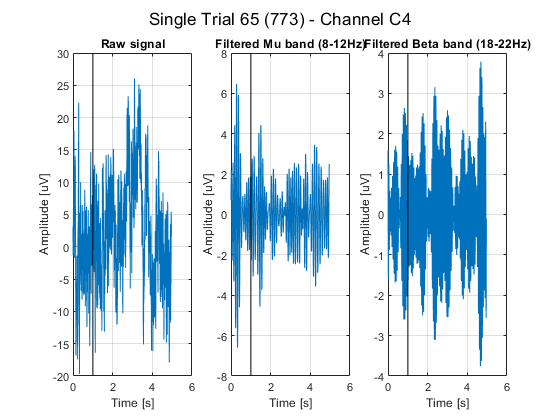

% selected channel and trial to plot
selected_channel = 11; % C4
selected_trial = 65;

figure;
selected_trial_index = (trial_k == selected_trial);
x_axis = linspace(0, sum(selected_trial_index)/info.sample_rate, sum(selected_trial_index));


subplot(1, 3, 1)
plot(x_axis, eeg(selected_trial_index, selected_channel));
xlabel('Time [s]');
ylabel('Amplitude [uV]');
title('Raw signal');
grid on;
line([1 1],get(gca,'YLim'),'Color',[0 0 0])

subplot(1, 3, 2)
plot(x_axis, mu_filtered_eeg(selected_trial_index, selected_channel));
xlabel('Time [s]');
ylabel('Amplitude [uV]');
title(['Filtered Mu band (' num2str(band_mu(1)) '-' num2str(band_mu(2)) 'Hz)']);
grid on;
line([1 1],get(gca,'YLim'),'Color',[0 0 0])

subplot(1, 3, 3)
plot(x_axis, beta_filtered_eeg(selected_trial_index, selected_channel));
xlabel('Time [s]');
ylabel('Amplitude [uV]');
title(['Filtered Beta band (' num2str(band_beta(1)) '-' num2str(band_beta(2)) 'Hz)']);
grid on;
line([1 1],get(gca,'YLim'),'Color',[0 0 0])

sgtitle(['Single Trial ' num2str(selected_trial) ' (' num2str(tCk(selected_trial)) ') - Channel ' info.channel_labels{selected_channel}]);

## Visualization 2

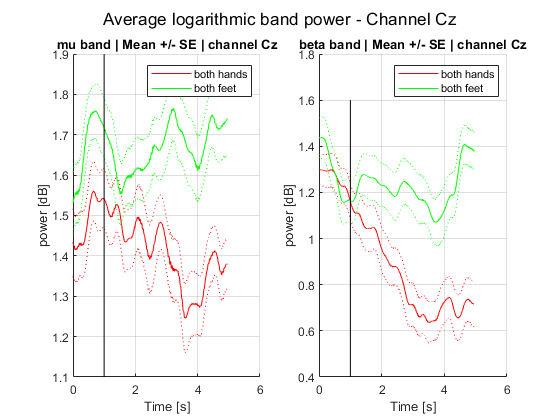

figure;
x_axis = linspace(0, min_trial_duration/info.sample_rate, min_trial_duration);
selected_channel = 9; 
colors = {'r', 'g'};
num_classes = length(info.classes);

subplot(1, 2, 1);
h_mu = nan(num_classes, 1);
for class_i = 1:num_classes
    hold on;
    cue_index = (tCk == classes(class_i));
    all_trials_mu = trial_mu_data(:, selected_channel, cue_index);
    average_mu = mean(all_trials_mu, 3);
    standard_error = std(all_trials_mu/sqrt(num_trials/2), [], 3);
    h_mu(class_i) = plot(x_axis, average_mu, colors{class_i});
    plot(x_axis, average_mu + standard_error, [colors{class_i} ':']);
    plot(x_axis, average_mu - standard_error, [colors{class_i} ':']);
    hold off;
end
title(['mu band | Mean +/- SE | channel ' info.channel_labels{selected_channel}]);
xlabel('Time [s]');
ylabel('power [dB]');
line([1 1],get(gca,'YLim'),'Color',[0 0 0])
grid on;
legend(h_mu, 'both hands', 'both feet');

subplot(1, 2, 2);
h_beta = nan(num_classes, 1);
for class_i = 1: num_classes
    hold on;
    cue_index = (tCk == classes(class_i));
    all_trials_beta = trial_beta_data(:, selected_channel, cue_index);
    average_beta = mean(all_trials_beta, 3);
    standard_error = std(all_trials_beta/sqrt(num_trials/2), [], 3);
    h_beta(class_i) = plot(x_axis, average_beta, colors{class_i});
    plot(x_axis, average_beta + standard_error, [colors{class_i} ':']);
    plot(x_axis, average_beta - standard_error, [colors{class_i} ':']);
    hold off;
end
title(['beta band | Mean +/- SE | channel ' info.channel_labels{selected_channel}]);
xlabel('Time [s]');
ylabel('power [dB]');
line([1 1],get(gca,'YLim'),'Color',[0 0 0])
grid on;
legend(h_beta, 'both hands', 'both feet');


sgtitle(['Average logarithmic band power - Channel ' info.channel_labels{selected_channel}]);

# ERD and ERS

Concatenate data and create cue and trial vectors

[psd, events, run_k, mode_k] = concatenatePSD(PSD_data);
[cue_k, trial_k] = labelData(events, size(psd, 1));

% Extract the desired frequencies.
[psd, psd_frequencies] = extractFrequencies(psd, original_frequencies, info.selected_frequencies);

% Apply log to psd
psd = log(psd);

# Power spectral density